load('matlab_output_LFPo09.mat')

% inspect table
head(bpodTableAll)

session_uniq = unique(bpodTableAll.SessionDate)

t = tiledlayout('flow')

ans = 3×1 categorical array
     LFPo10 
     LFPo11 
     LFPo08 


for i = 1: length(session_uniq)
    B = bpodTableAll(bpodTableAll.SessionDate == session_uniq(i), :);

session_uniq = 15×1 datetime array
   15-Feb-2021
   16-Feb-2021
   17-Feb-2021
   18-Feb-2021
   19-Feb-2021
   20-Feb-2021
   21-Feb-2021
   22-Mar-2021
   23-Mar-2021
   24-Mar-2021
   25-Mar-2021
   26-Mar-2021
   27-Mar-2021
   28-Mar-2021
   29-Mar-2021


    nexttile
    histogram(B.TResponseTime, "BinWidth", 0.05)

t =   TiledChartLayout with properties:

    TileArrangement: 'flow'
           GridSize: [1 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


    ttle = strcat(string(B.Protocol(i)), ": ", string(B.SessionDate(i)));
    title(ttle)
    xlabel("Reaction Time (in s)")
    ylabel("Count")
    xlim([0 4])
end

title(t, "Aggregated from 17 mice of Pf Caspase Experiment")

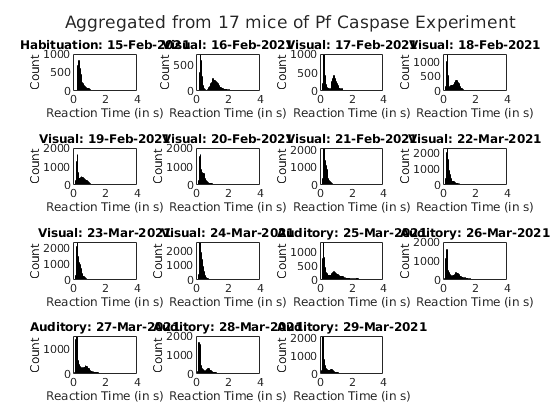

% DO NOT DELETE
% Use this for older versions of MATLAB


session_uniq = unique(B_aud.SessionDate);
row_nums = ceil(length(session_uniq)/3);

for k = 1: length(session_uniq)
    ax = subplot(row_nums, 3, k);
    B2 = B_aud(B_aud.SessionDate == session_uniq(k), :);
    boxplot(B2.percentCorrect, B2.Group, "ColorGroup",colors)
    ylim([0, 1.1])
    ylabel("Percent Correct", "FontSize", 8);
    
    ax.XDir = "reverse";
    t = title(string(session_uniq(k)));
    t.FontSize = 8;
    t.FontWeight = "bold";
    pbaspect(ax, ([1, 1.1, 1]))
end  